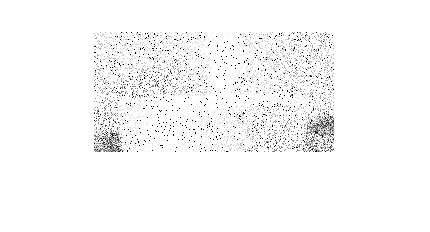

rng(100);
A = mmread('flame.avi');
T = 5;
for i=1:T
    Z(:,:,i) = double(rgb2gray(A.frames(i).cdata));
end
X1 = Z(139:258,56:295, :);
[H,W,T] = size(X1);
C = randi([0 1], H,W,T);
C1 = min(C+randi([0 1], H,W,T)+randi([0 1], H,W,T), 1);
%imshow(Z(139:258,56:295, 1)/255);
E = sum(C.*X1, 3);
noise = randn(H,W)*2;
E1 = E+noise;
imshow(E1/255);

recon = double(zeros(120, 240, T));
a = dctmtx(8);
b = dctmtx(T);
DCT3 = kron(kron(a,a),b);
I_final = double(zeros(120, 240, T));
I_n = zeros(120, 240, T);
for i=1:113
    for j=1:233
        phi = double(zeros(64, 64*T));
        for b=1:T
            diag1 = diag(reshape(C(i:i+7,j:j+7,b)', [], 1));
            phi(:,64*(b-1)+1:64*b) = diag1;
        end
        J = E1(i:i+7,j:j+7);
        y = reshape(J', [], 1);
        A = phi*DCT3;
        theta = OMP(A, A./vecnorm(A), y, 64*T);
        x = DCT3*theta;
        x_reshape = reshape(x', [8,8,T]);
        for k=1:T
            I_final(i:i+7,j:j+7,k) = I_final(i:i+7,j:j+7,k)+x_reshape(:,:,k)';
        end
        I_n(i:i+7, j:j+7, :) = I_n(i:i+7, j:j+7, :) + 1;
    end
end
I_final1 = I_final./I_n;
error = sqrt(sum((E1-I_final1).^2, "all")/(sum(E1.^2, "all")))

error = 1.5401

I_final = uint8(max(I_final./I_n,0));
v = VideoWriter("myvideo_flame_"+T+".avi", 'Grayscale AVI');
open(v);
writeVideo(v, reshape(I_final,[120,240,1,T]));
close(v)


